
fs = 44100; 
duration = 3; 


recObj = audiorecorder(fs, 16, 1);


disp('Recording reference keylock...');

Recording reference keylock...


recordblocking(recObj, duration); 
disp('Recording finished.');

Recording finished.


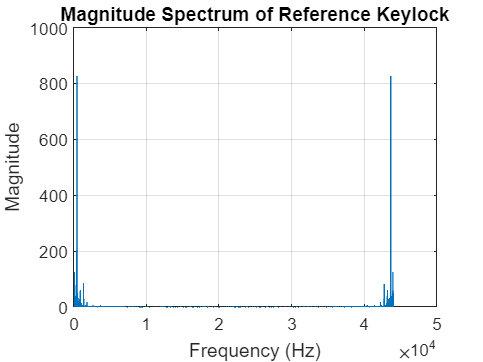



reference_audio = getaudiodata(recObj);
audiowrite('reference.wav', reference_audio, fs)


[reference_audio, fs] = audioread('reference.wav');


N = length(reference_audio);
frequencies = (0:(N-1)) * fs / N;
magnitude_spectrum = abs(fft(reference_audio));


threshold = max(magnitude_spectrum) * 0.1; 
fundamental_frequency = frequencies(find(magnitude_spectrum > threshold, 1));


figure;
plot(frequencies, magnitude_spectrum);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of Reference Keylock');
grid on;


fprintf('Fundamental Frequency of Reference Keylock: %.2f Hz\n', fundamental_frequency);

Fundamental Frequency of Reference Keylock: 149.33 Hz


function access_status = check_access(audio_file, reference_frequency, error_tolerance)
    
    [recorded_audio, fs] = audioread(audio_file);
    
    
    N = length(recorded_audio);
    magnitude_spectrum = abs(fft(recorded_audio));

   
    threshold = max(magnitude_spectrum) * 0.1; 
    recorded_frequency = frequencies(find(magnitude_spectrum > threshold, 1));

    
    if abs(recorded_frequency - reference_frequency) <= error_tolerance
        access_status = 'ACCESS GRANTED';
    else
        access_status = 'ACCESS DENIED';
    end
end

